# **Matlab案例代码解析**

## 5. 智能优化算法案例

### 5.1 差分进化（DE）

#### 5.1.2 离散DE求解函数极值

- 针对整数变量，用floor函数向下取整：$v_{i,G+1}=floor(x_{r1,G}+F*(x_{r2,G}-x_{r3,G}))$

%%%%%%%%%%%%%  离散差分进化算法求函数极值 %%%%%%%%%%%%%
%%%%%%%%%%%%%  初始化 %%%%%%%%%%%%%
clear;clc;
% 种群数量
NP = 20;   
% 变量维度
D = 2;       
% 最大进化代数
G = 200;      
% 初始编译算子
F = 0.5;     
% 交叉算子
CR = 0.1;  
% 上限
Xs = 100;  
% 下限
Xx = -100;                            
%%%%%%%%%%%%%  赋初值 %%%%%%%%%%%%%
Ob = zeros(NP, 1);
Ob1 = zeros(NP, 1);
trace = zeros(G + 1, 1);
% 变异种群
v = zeros(D, NP);  
% 选择种群
u = zeros(D, NP);    
% 初始种群
x = randi([Xx, Xs], D, NP);  
%%%%%%%%%%%%%  计算目标函数 %%%%%%%%%%%%%
for m = 1:NP
   Ob(m) = ObjFunInt(x(:, m));
end
trace(1) = min(Ob);
%%%%%%%%%%%%%  差分进化循环 %%%%%%%%%%%%%
for gen = 1:G
   %%%%%%%%%%%%%  变异操作 %%%%%%%%%%%%%
   %%%%%%%%%%  r1、r2、r3和m互不相同 %%%%%%%%%%
   for m = 1:NP
      r1 = randi([1, NP], 1);
      while r1 == m
         r1 = randi([1, NP], 1);
      end
      r2 = randi([1, NP], 1);
      while r2 == m || r2 == r1
         r2 = randi([1, NP], 1);
      end
      r3 = randi([1, NP], 1);
      while r3 == m || r3 == r2 || r3 == r1
         r3 = randi([1, NP], 1);
      end
      v(:, m) = floor(x(:, r1) + F*(x(:, r2) - x(:, r3)));
   end
   %%%%%%%%%%%%%  交叉操作 %%%%%%%%%%%%%
   r = randi([1, D], 1);
   for n = 1:D
      cr = rand;
      if cr <= CR || n == r
         u(n, :) = v(n, :);
      else
         u(n, :) = x(n, :);
      end
   end
   %%%%%%%%%%%%%  边界条件的处理 %%%%%%%%%%%%%
   %%%%%%%%%%%%%  边界吸收 %%%%%%%%%%%%%
   for n = 1:D
      for m = 1:NP
         if u(n, m) < Xx
            u(n, m) = Xx;
         end
         if u(n, m) > Xs
            u(n, m) = Xs;
         end
      end
   end
   %%%%%%%%%%%%%  选择操作 %%%%%%%%%%%%%
   for m = 1:NP
      Ob1(m) = ObjFunInt(u(:, m));
   end
   for m = 1:NP
      if Ob1(m) > Ob(m)
         x(:, m) = u(:, m);
      end
   end
   for m = 1:NP
      Ob(m) = ObjFunInt(x(:, m));
   end
   trace(gen + 1) = min(Ob);
end
[SortOb, Index] = sort(Ob);
x = x(:, Index);
% 最优变量
X = x(:, 1);   
% 最优值
Y = min(Ob);                 
disp(['最优x：' num2str(X')]);

最优x：-2 -3


disp(['最优y：' num2str(Y)]);

最优y：10


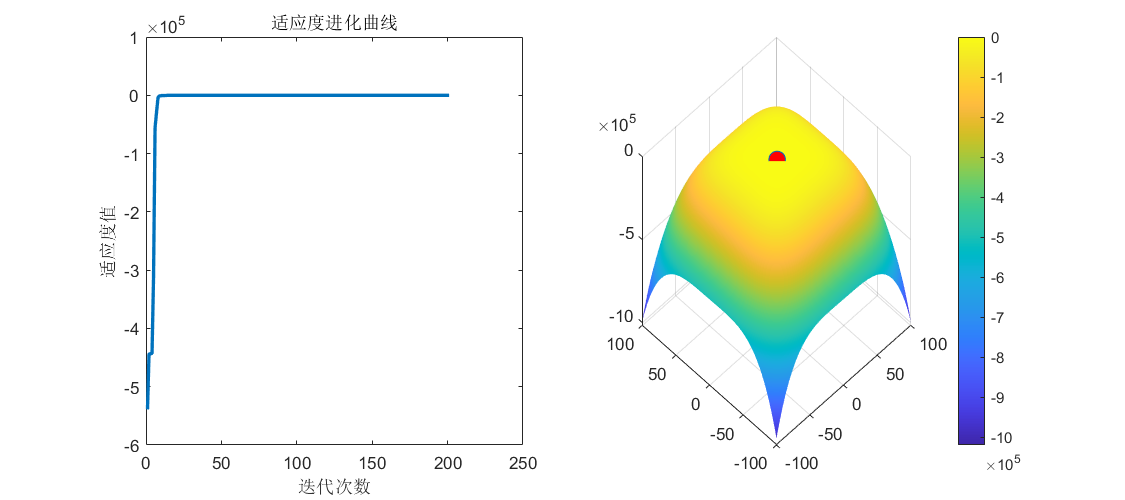

subplot(1, 2, 1)
plot(trace, 'LineWidth', 2);
xlabel('迭代次数');
ylabel('适应度值');
title('适应度进化曲线');
len = 200;
xRange = linspace(Xx, Xs, len);
yRange = linspace(Xx, Xs, len);
[xMap, yMap] = meshgrid(xRange, yRange);
zMap = zeros(len);
for i = 1 : len
    for j = 1 : len
        zMap(i, j) = ObjFunInt([xMap(i, j), yMap(i, j)]);
    end
end
subplot(1, 2, 2)
surf(xRange, yRange, zMap);
colorbar;
view(-45, 45);
shading interp
hold on
plot3(X(1), X(2), Y, 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 10);
hold off
set(gcf, 'Position', [400, 200, 900, 400]);

function result = ObjFunInt(x)
result = -((x(1).^2 + x(2) - 1).^2 + (x(1) + x(2).^2 - 7).^2)/200 + 10;
end